# **Binary occupancy map**

***In the first step, a binary occupancy map of size 10x10 meters with a resolution of 10 cells per meter is created. Two polygonal obstacles (a rectangle and an irregular quadrilateral) and two circular obstacles are added to the map. The ***`setOccupancy`*** function marks these areas as occupied (value 1). Finally, the obstacles are inflated by 0.5 meters to account for robot size or safety margins.***

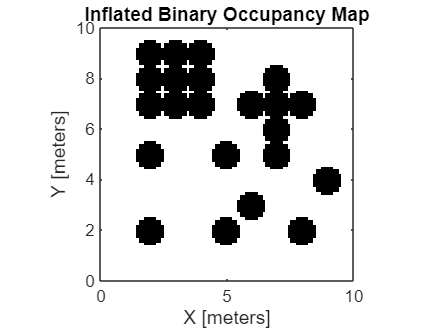

clc; clear; close all;

%% Create Binary Occupancy Map
map = binaryOccupancyMap(10, 10, 10);

% --- Add First Polygon (Rectangle) ---
x_poly1 = [2, 2, 5, 5];  % X-coordinates
y_poly1 = [2, 5, 5, 2];  % Y-coordinates
setOccupancy(map, [x_poly1; y_poly1]', 1);

% --- Add Second Polygon (Irregular Quadrilateral) ---
x_poly2 = [6, 7, 9, 8];  % X-coordinates
y_poly2 = [3, 5, 4, 2];  % Y-coordinates
setOccupancy(map, [x_poly2; y_poly2]', 1);

% --- Add First Circular Obstacle ---
[x_grid, y_grid] = meshgrid(1:map.XWorldLimits(2), 1:map.YWorldLimits(2));
circle1_mask = (x_grid - 3).^2 + (y_grid - 8).^2 <= 1.5^2; % Center (3,8), radius 1.5
[row, col] = find(circle1_mask);
setOccupancy(map, [col, row], 1);

% --- Add Second Circular Obstacle ---
circle2_mask = (x_grid - 7).^2 + (y_grid - 7).^2 <= 1^2; % Center (7,7), radius 1
[row, col] = find(circle2_mask);
setOccupancy(map, [col, row], 1);

% Inflate the obstacles by 0.5 meters
inflate(map, 0.5);
% Display the inflated occupancy map
figure;
show(map);
title('Inflated Binary Occupancy Map');

***These points represent the robot's initial and target locations on the map.***

%% Define Start and Goal
start = [0.5, 0.5, 0];  % (x, y, theta)
goal = [9, 9, 0];

***In this step, variables are initialized to store performance metrics for comparing the PRM, RRT, and RRT* algorithms. These include execution times, path lengths, success counts, and the number of nodes generated. The algorithms will be run for ***`numTrials = 5`*** iterations to gather data for comparison.***

%% Comparison Parameters
numTrials = 5;
rrtTimes = zeros(numTrials, 1);
prmTimes = zeros(numTrials, 1);
rrtStarTimes = zeros(numTrials, 1);
rrtPathLengths = zeros(numTrials, 1);
prmPathLengths = zeros(numTrials, 1);
rrtStarPathLengths = zeros(numTrials, 1);
rrtSuccesses = 0;
prmSuccesses = 0;
rrtStarSuccesses = 0;
rrtNodes = zeros(numTrials, 1);
rrtStarNodes = zeros(numTrials, 1);

# **RRT (Rapidly-exploring Random Tree)**

***This step runs the RRT (Rapidly-exploring Random Tree) algorithm for ***`numTrials`*** iterations to find a path between the start and goal positions. For each trial, an inflated copy of the map is created to account for robot clearance. A Dubins state space with a minimum turning radius of 0.4 is defined, along with an occupancy map validator. The RRT planner is configured with a maximum connection distance of 0.5 meters and 30,000 iterations. Execution time, path length, and the number of nodes are recorded if a valid path is found.***

%% Run RRT Trials
for i = 1:numTrials
    tic;
    inflatedMap = copy(map);
    inflate(inflatedMap, 0.1);
    bounds = [inflatedMap.XWorldLimits; inflatedMap.YWorldLimits; [-pi pi]];
    ss = stateSpaceDubins(bounds);
    ss.MinTurningRadius = 0.4;
    validator = validatorOccupancyMap(ss);
    validator.Map = inflatedMap;
    validator.ValidationDistance = 0.5;
    planner = plannerRRT(ss, validator);
    planner.MaxConnectionDistance = 0.5;
    planner.MaxIterations = 30000;
    [pthObj, solnInfo] = plan(planner, start, goal);
    rrtTimes(i) = toc;
    if ~isempty(pthObj.States)
        rrtSuccesses = rrtSuccesses + 1;
        rrtPathLengths(i) = pathLength(pthObj);
        rrtNodes(i) = size(solnInfo.TreeData, 1);
    end
end

# **RRT* (Rapidly-exploring Random Tree Star) algorithm **

%% Run RRT* Trials
for i = 1:numTrials
    tic;
    plannerStar = plannerRRTStar(ss, validator);
    plannerStar.MaxConnectionDistance = 0.5;
    plannerStar.MaxIterations = 30000;
    [pthObjStar, solnInfoStar] = plan(plannerStar, start, goal);
    rrtStarTimes(i) = toc;
    if ~isempty(pthObjStar.States)
        rrtStarSuccesses = rrtStarSuccesses + 1;
        rrtStarPathLengths(i) = pathLength(pthObjStar);
        rrtStarNodes(i) = size(solnInfoStar.TreeData, 1);
    end
end

# **PRM (Probabilistic Roadmap) algorithm**

***In this step, the PRM (Probabilistic Roadmap) algorithm is run for ***`numTrials`*** iterations to find a path between the start and goal positions. A PRM object is created with 200 nodes on the binary occupancy map. The ***`findpath`*** function searches for a valid path, and if successful, the execution time and path length are recorded. Successful trials are counted to evaluate the algorithm's performance.***

%% Run PRM Trials
for i = 1:numTrials
    tic;
    prm = mobileRobotPRM(map, 200);
    path = findpath(prm, start(1:2), goal(1:2));
    prmTimes(i) = toc;
    if ~isempty(path)
        prmSuccesses = prmSuccesses + 1;
        prmPathLengths(i) = sum(vecnorm(diff(path),2,2));
    end
end

**In this step, key performance statistics are calculated for the RRT, RRT*, and PRM algorithms. These include the average execution time, average path length (for successful trials), and success rates for each algorithm. Additionally, the average number of nodes generated during successful RRT and RRT* trials is computed to compare their efficiency and performance.**

%% Compute Statistics
avg_rrt_time = mean(rrtTimes);
avg_prm_time = mean(prmTimes);
avg_rrtStar_time = mean(rrtStarTimes);
avg_rrt_length = mean(rrtPathLengths(rrtPathLengths > 0));
avg_prm_length = mean(prmPathLengths(prmPathLengths > 0));
avg_rrtStar_length = mean(rrtStarPathLengths(rrtStarPathLengths > 0));
rrt_success_rate = (rrtSuccesses / numTrials) * 100;
prm_success_rate = (prmSuccesses / numTrials) * 100;
rrtStar_success_rate = (rrtStarSuccesses / numTrials) * 100;
avg_rrt_nodes = mean(rrtNodes(rrtNodes > 0));
avg_rrtStar_nodes = mean(rrtStarNodes(rrtStarNodes > 0));

%% Display Results
fprintf('\n=== RRT vs PRM vs RRT* Comparison Results ===\n');


=== RRT vs PRM vs RRT* Comparison Results ===


fprintf('Avg. Computation Time: RRT = %.4f sec, PRM = %.4f sec, RRT* = %.4f sec\n', avg_rrt_time, avg_prm_time, avg_rrtStar_time);

Avg. Computation Time: RRT = 0.1189 sec, PRM = 0.4080 sec, RRT* = 0.0696 sec


fprintf('Avg. Path Length: RRT = %.4f, PRM = %.4f, RRT* = %.4f\n', avg_rrt_length, avg_prm_length, avg_rrtStar_length);

Avg. Path Length: RRT = 15.2174, PRM = 13.1058, RRT* = 15.7000


fprintf('Success Rate: RRT = %.2f%%, PRM = %.2f%%, RRT* = %.2f%%\n', rrt_success_rate, prm_success_rate, rrtStar_success_rate);

Success Rate: RRT = 100.00%, PRM = 100.00%, RRT* = 100.00%


fprintf('Avg. Nodes Explored in RRT: %.2f, RRT*: %.2f\n', avg_rrt_nodes, avg_rrtStar_nodes);

Avg. Nodes Explored in RRT: 872.60, RRT*: 463.40


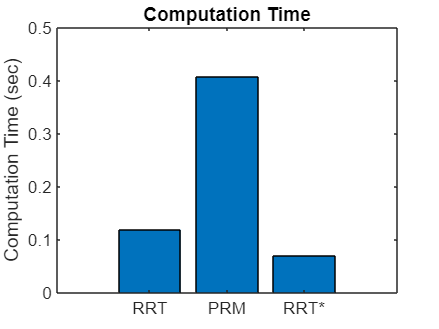


%% Plot Comparison Results
figure; bar([avg_rrt_time, avg_prm_time, avg_rrtStar_time]); set(gca, 'XTickLabel', {'RRT', 'PRM', 'RRT*'}); ylabel('Computation Time (sec)'); title('Computation Time');

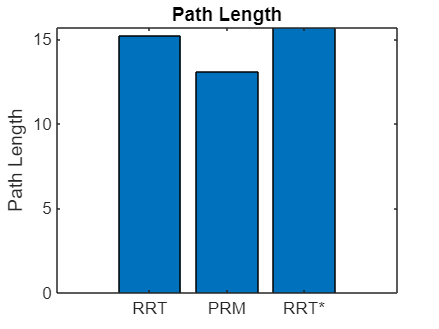

figure; bar([avg_rrt_length, avg_prm_length, avg_rrtStar_length]); set(gca, 'XTickLabel', {'RRT', 'PRM', 'RRT*'}); ylabel('Path Length'); title('Path Length');

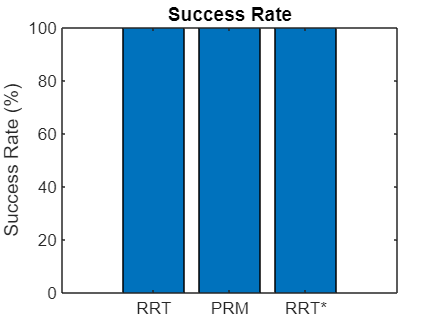

figure; bar([rrt_success_rate, prm_success_rate, rrtStar_success_rate]); set(gca, 'XTickLabel', {'RRT', 'PRM', 'RRT*'}); ylabel('Success Rate (%)'); title('Success Rate');

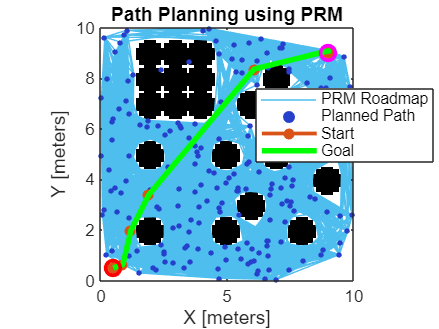

% Display results
figure;
show(map);
hold on;
% Plot PRM Roadmap
show(prm);
% Plot the path
if ~isempty(path)
    plot(path(:,1), path(:,2), 'g-', 'LineWidth', 3);
end
% Show start and goal points
plot(start(1), start(2), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
plot(goal(1), goal(2), 'mo', 'MarkerSize', 8, 'LineWidth', 2);
legend('PRM Roadmap', 'Planned Path', 'Start', 'Goal');
title('Path Planning using PRM');
hold off;

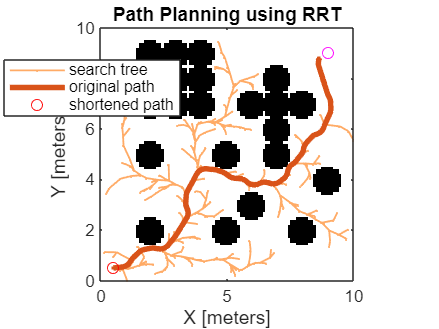

figure;
show(map)
hold on
% Plot entire search tree.
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),plannerLineSpec.tree{:})
% Interpolate and plot path.
interpolate(pthObj,300)
plot(pthObj.States(:,1),pthObj.States(:,2),plannerLineSpec.path{:})
% Show start and goal in grid map.
plot(start(1),start(2),'ro')
plot(goal(1),goal(2),'mo')
legend('search tree','original path','shortened path')
title('Path Planning using RRT');
hold off

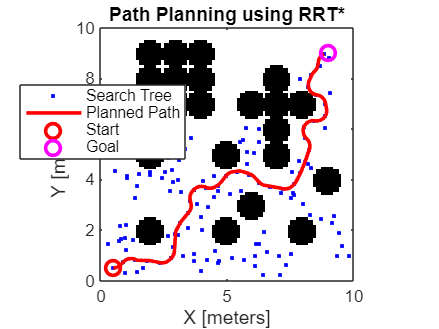


figure;
show(map)
hold on
% Plot entire RRT* search tree.
plot(solnInfoStar.TreeData(:,1), solnInfoStar.TreeData(:,2), 'b.');
% Interpolate and plot the RRT* path.
if ~isempty(pthObjStar.States)
    interpolate(pthObjStar, 300);
    plot(pthObjStar.States(:,1), pthObjStar.States(:,2), 'r-', 'LineWidth', 2);
end
% Show start and goal points.
plot(start(1), start(2), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
plot(goal(1), goal(2), 'mo', 'MarkerSize', 8, 'LineWidth', 2);
legend('Search Tree', 'Planned Path', 'Start', 'Goal');
title('Path Planning using RRT*');
hold off;

# **Comparison and Experimentation:**

## `(Test:1)`

### `=== RRT vs PRM vs RRT* Comparison Results ===`

**When **` planner.MaxConnectionDistance = 2.5;For both RRT and RRT*`

`And node of prm is 50`

`Avg. Computation Time: RRT = 0.0281 sec, PRM = 0.0287 sec, RRT* = 0.0452 sec`

`Avg. Path Length: RRT = 15.6093, PRM = 14.0299, RRT* = 18.3082`

`Success Rate: RRT = 100.00%, PRM = 100.00%, RRT* = 100.00%`

`Avg. Nodes Explored in RRT: 153.80, RRT*: 210.20`

## `(Test:2)`

### `=== RRT vs PRM vs RRT* Comparison Results ===`

**When **` planner.MaxConnectionDistance = 1.5; For both RRT and RRT*`

`And node of prm is 100`

`Avg. Computation Time: RRT = 0.0603 sec, PRM = 0.1441 sec, RRT* = 0.0480 sec`

`Avg. Path Length: RRT = 16.0027, PRM = 13.5594, RRT* = 15.9970`

`Success Rate: RRT = 100.00%, PRM = 100.00%, RRT* = 100.00%`

`Avg. Nodes Explored in RRT: 366.80, RRT*: 194.60`

## `(Test:3)`

### `=== RRT vs PRM vs RRT* Comparison Results ===`

**When **` planner.MaxConnectionDistance = 1.0; For both RRT and RRT*`

`And node of prm is 150`

`Avg. Computation Time: RRT = 0.0810 sec, PRM = 0.5260 sec, RRT* = 0.0740 sec`

`Avg. Path Length: RRT = 15.4851, PRM = 13.6162, RRT* = 15.1425`

`Success Rate: RRT = 100.00%, PRM = 100.00%, RRT* = 100.00%`

`Avg. Nodes Explored in RRT: 392.60, RRT*: 270.80`

## `(Test:4)`

### `=== RRT vs PRM vs RRT* Comparison Results ===`

**When **` planner.MaxConnectionDistance = 0.5; For both RRT and RRT*`

`And node of prm is 200`

`Avg. Computation Time: RRT = 0.1321 sec, PRM = 0.8726 sec, RRT* = 0.1522 sec`

`Avg. Path Length: RRT = 15.1649, PRM = 13.0361, RRT* = 15.8653`

`Success Rate: RRT = 100.00%, PRM = 100.00%, RRT* = 100.00%`

`Avg. Nodes Explored in RRT: 663.80, RRT*: 612.20`

# **Analysis for my Results:**

## **1. Is PRM more efficient than RRT in a cluttered space?**

### **Computation Time:**

- PRM takes longer than RRT when the number of nodes increases (e.g., at 200 nodes, PRM takes **0.8726 sec**, while RRT takes **0.1321 sec**).

- At lower node counts (e.g., 50), PRM and RRT have nearly the same execution time.

- RRT is more efficient when fewer nodes are explored.

### **Observation:**

- In a cluttered space, PRM can be **slower** than RRT if the number of nodes is high.

- However, PRM finds shorter paths, making it more **optimal** in terms of path length.

## **2. Which algorithm generates the shortest paths?** 

### **Path Lengths:**

- PRM consistently produces the shortest paths, **ranging from 13.0361 to 14.0299**.

- RRT* is expected to refine the path over time, but in my results, it doesn't always outperform RRT in terms of path length.

- RRT and RRT* paths are **longer than PRM** across all scenarios.

# **Conclusion:**

- PRM generates the shortest paths.

- RRT is supposed to optimize paths, but in my tests, it sometimes results in longer paths than RRT itself.* This could be due to insufficient iterations for path optimization.

## **3. How can algorithm efficiency be improved?** 

### **For PRM:**

- Increase node count **gradually** to balance path length and computation time.

- Use **adaptive sampling** to place more nodes in complex regions instead of uniform sampling.

### For RRT & RRT:*

- **Increase MaxConnectionDistance** to reduce the number of nodes while keeping paths feasible. 

- Use **post-processing techniques** like **shortcutting** or **smoothing** to refine paths. 

- Reduce **MaxIterations** to limit search complexity.

### **General Recommendations:**  

- Use **RRT when speed is needed.** 

- Use **PRM when path length is the priority.**

- Use *RRT when path optimization is necessary, but ensure enough iterations for refinement.**

***Some of the functions I used in the Movement Planning Navigation Toolbox in MATLAB are available on the official website. Here is the referenece "https://fr.mathworks.com/help/nav/motion-planning.html"***